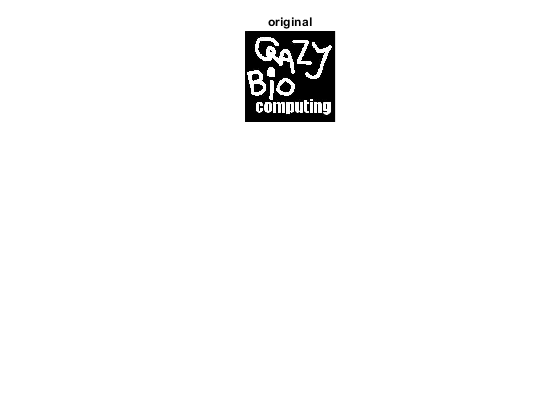

I = imread('crazyBioComp.jpg');
fig = figure();
subplot(3,3,2)
imshow(I)
title('original')

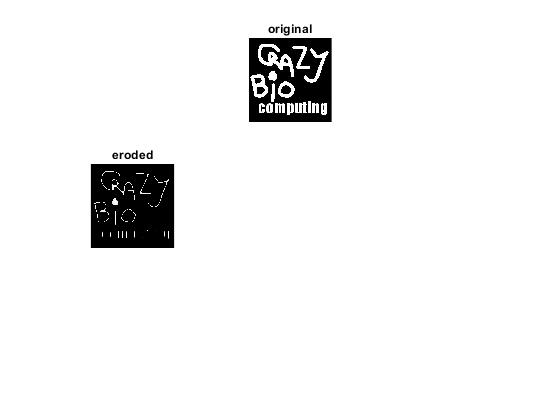

SE1 = strel('disk',5);
I_eroded = imerode(I,SE1);
subplot(3,3,4)
imshow(I_eroded)
title('eroded')

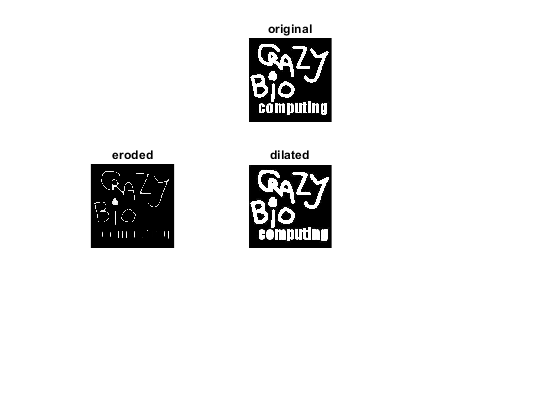

SE1 = strel('cube',2);
I_dilated = imdilate(I,SE1);
subplot(3,3,5)
imshow(I_dilated)
title('dilated')

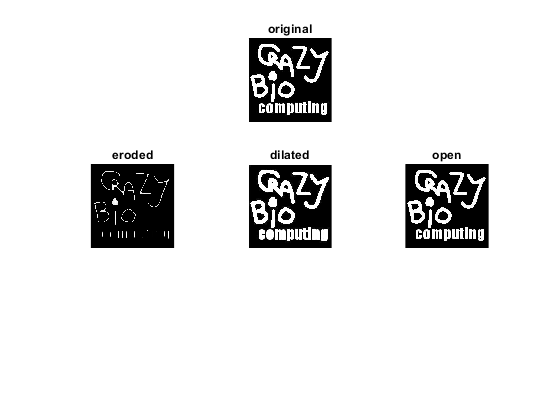

I_open = imopen(I,SE1);
subplot(3,3,6)
imshow(I_open)
title('open')

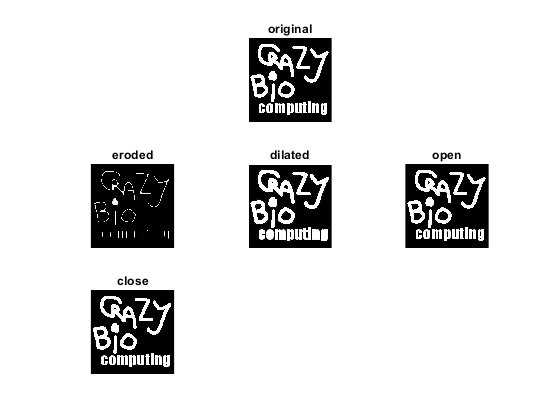

I_close = imclose(I,SE1);
subplot(3,3,7)
imshow(I_open)
title('close')

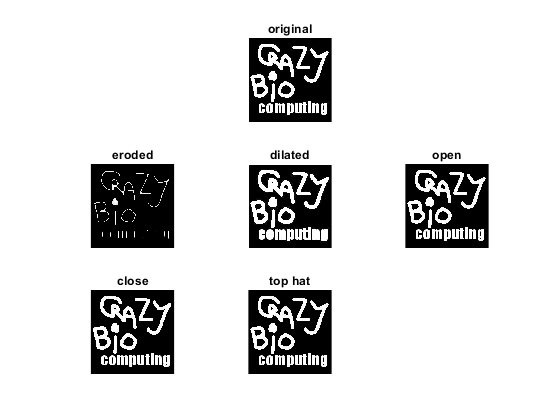

I_tophat = imtophat(I,SE1);
subplot(3,3,8)
imshow(I_open)
title('top hat')

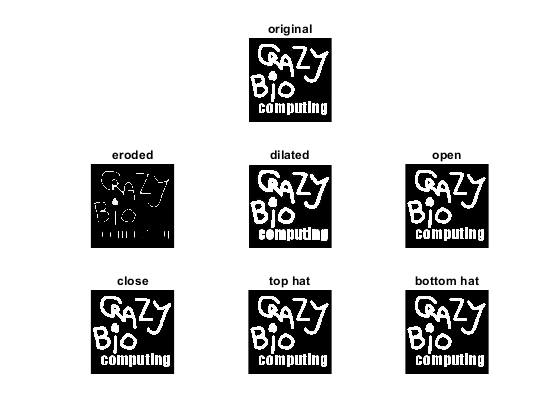

I_bothat = imbothat(I,SE1);
subplot(3,3,9)
imshow(I_open)
title('bottom hat')

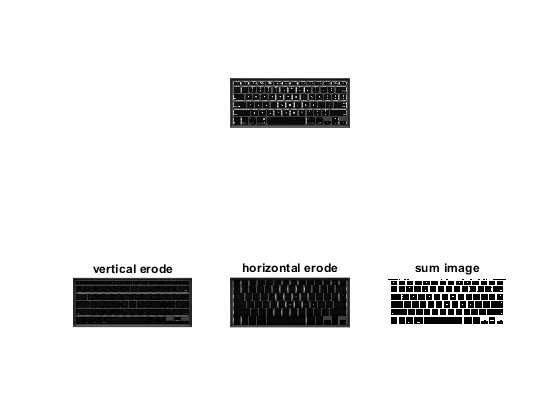

I2 = imread('keyboard.jpg');
fig = figure;
subplot(2,3,2);
imshow(I2)
SE2 = strel('line',8,0);
SE3 = strel('line',8,90);
SE4 = strel('square',8);
I_erode1 = imerode(I2,SE2);
subplot(2,3,4);
imshow(I_erode1)
title('vertical erode')
I_erode2 = imerode(I2,SE3);
subplot(2,3,5);
imshow(I_erode2)
title('horizontal erode')
sum_I = I_erode1 + I_erode2;
sum_I = im2bw(sum_I,0.2);
subplot(2,3,6);
imshow(sum_I)
title('sum image')
saveas(fig,'Q1-3.jpg')

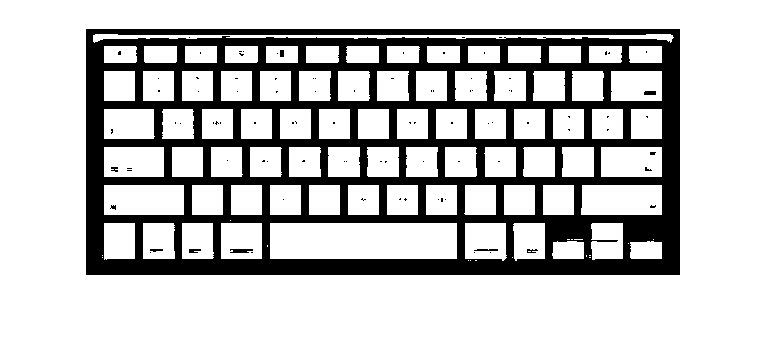

I2 = imread('keyboard.jpg');
I2_not = ~sum_I;
fig = figure;
imshow(I2_not)

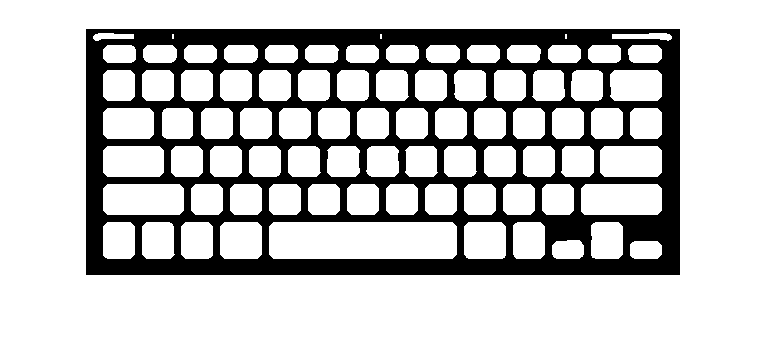

filtered = medfilt2(I2_not,[8 8]);
imshow(filtered)

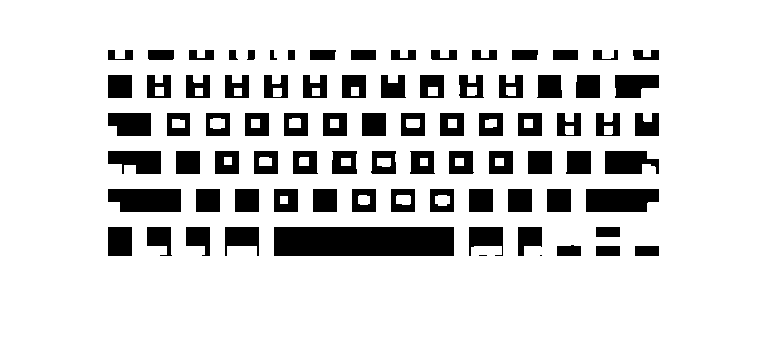

sum_I_dilate = imdilate(sum_I,SE4);
imshow(sum_I_dilate)

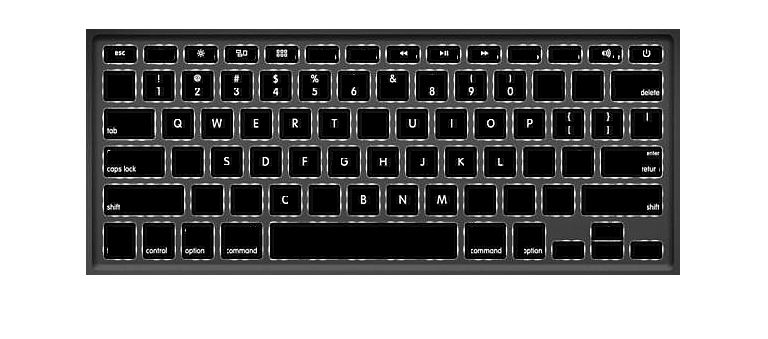

total_im = uint8(sum_I_dilate).*I2;
total_im = imsharpen(total_im);
imshow(total_im)

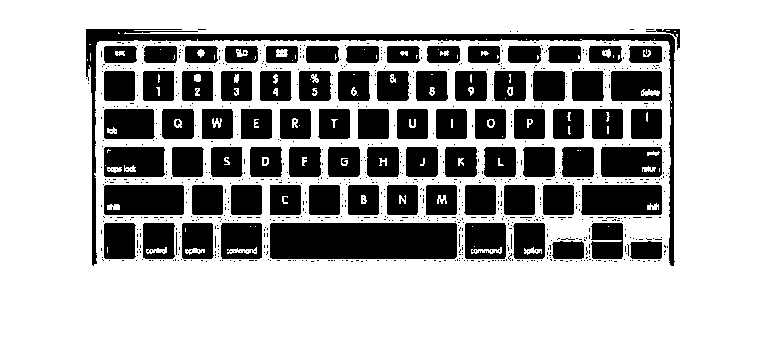

imshow(im2bw(total_im,0.2))

selfie = imread('IMG_4717.jpg');
selfie = imrotate(selfie,-90);
selfie = imresize(selfie,[400 300]);
selfie = rgb2gray(selfie);
selfie = imgaussfilt(selfie,0.5);
fig = figure;
subplot(2,3,2)
imshow(selfie)
title('Original')
subplot(2,3,4)
imshow(edge(selfie,'Sobel',0.03))
title('Sobel edge')
subplot(2,3,5)
imshow(edge(selfie,'Roberts',0.03))
title('Roberts edge')
subplot(2,3,6)
imshow(edge(selfie,'Canny',0.2))
title('Canny edge')
saveas(fig,'Q2-2.jpg')

a = realp('a',-1);
op = [0 -a 0; -a 1+4*a -a; 0 -a 0];
vals = [0 1 2 3 4];
fig = figure();
for i = 1:1:4
    subplot(2,2,i)
    op.Blocks.a.Value = vals(i);
    tmp_img = imfilter(selfie,double(op));
    imshow(clip(tmp_img),[]);
    title(['a = ' num2str(i)])
end
saveas(fig,'Q2-3.jpg')

noised_selfie = imnoise(selfie,'salt & pepper',0.06)
vals = [0.3 0.5 0.7];
fig = figure();
subplot(2,3,2)
imshow(noised_selfie,[])
for i = 1:1:3
    subplot(2,3,i+3)
    op.Blocks.a.Value = vals(i);
    tmp_img = imfilter(noised_selfie,double(op));
    imshow(clip(tmp_img),[]);
    title(['a = ' num2str(vals(i))])
end
saveas(fig,'Q2-4.jpg')

noised_filtered = medfilt2(noised_selfie)
vals = [0.3 0.5 0.7];
fig = figure();
subplot(2,3,2)
imshow(noised_filtered,[])
for i = 1:1:3
    subplot(2,3,i+3)
    op.Blocks.a.Value = vals(i);
    tmp_img = imfilter(noised_filtered,double(op));
    imshow(clip(tmp_img),[]);
    title(['a = ' num2str(vals(i))])
end
saveas(fig,'Q2-5.jpg')
